# **Tutorial: Information Breakdown**

This tutorial provides an introduction to the Information Breakdown of the MINT toolbox. 

Neural signals recorded from different brain regions are often correlated, meaning that activity patterns across these regions show interdependencies over both space and time. This widespread correlation raises important questions about how these interdependent neural signals collectively convey information about sensory stimuli and how these correlations effect the information content that can be extracted from a group of simultaneously recorded neurons.

**Mutual information** is a measure that captures the total information we can obtain about a sensory stimulus S by observing the neural response **R**. However, mutual information alone doesn’t reveal how correlations within the neural population—between both signal and noise components—contribute to this total information.

**Information Breakdown** is a method that decomposes the total mutual information I(S;R) into three components, each highlighting a distinct way in whIch signal and noise correlations affect information transmIssion:

- **linear information component I_lin:** This term represents the sum of the information provided by each neuron’s response independently, without accounting for correlations. It reflects the baseline amount of information that would be transmitted if each neuron acted independently.

- **Signal similarity component I_sig-sim**: This component, whIch is always zero or negative, measures the redundancy in the information due to correlations in the signal across neurons. When neurons respond similarly to the same stimulus, they convey overlapping information, leading to redundancy that reduces the unique information contributed by each neuron.

- **Noise correlation component I_cor**: This term captures the influence of noise correlations on information encoding. Noise correlations occur when random fluctuations in neural activity are synchronized across neurons, affecting how well we can distinguish different stimuli. Depending on the nature of these correlations, Icor can either enhance or diminish the information content of the neural population.

The mutual Information can be written as:

*I(S;****R****) =  I_lin + syn = I_lin + I_sig-sim + I_cor*

with* I_cor = I_cor-ind + I_cor-dep*

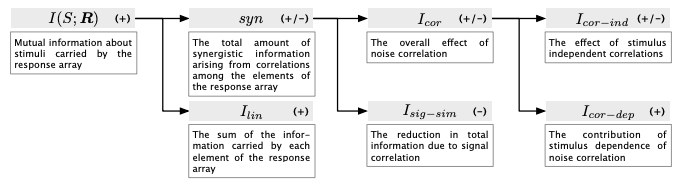

[Cesare Magri et al. “A toolbox for the fast information analysis of multiple-site LFP, EEG and spike train recordings”. In: BMC Neuroscience 10.1 (July 2009). doi: 10.1186/1471-2202-10-81]

## **How to compute Information Breakdown **

### Settings of MI to compute the Information breakdown

The `MI` function is designed to compute mutual information (MI) and related information-theoretIc measures between two sets of input data, referred to as A and B. These inputs are provided as a cell array, where `inputs{1}` corresponds to the first dataset (A) and `inputs{2}` corresponds to the second dataset (B). If either A, B, or both inputs are time series, the output will also be returned as a time series.

You can specify whIch types of entropy calculations you would like to perform by passing a cell array of strings in the `req`O`utputs` parameter. To compute the Information Breakdown components you can specify the following reqOutput strings: 

- 'I(A;B)'              : Mutual Information about the stimuli carried by the response array (Joint information)

- 'Ilin(A;B)'           : the sum of the information carried by each element of the response array (positive value)

- 'RSI(A;B)'          : the Redundancy-Synergy Index (negative: redundant encoding, positive: synergistic encoding)

- 'Iss(A)'              : the reduction in total information due to signal correlation (it's called Iss(A), because this measure is only dependent on the neural response) (negative value)

- 'Ic(A;B)'             : the overall effect of noise correlation (positive or negative value)

- 'Ici(A;B)'            : the effect of stimulus-independent correlations (positive or negative value)

- 'Icd(A;B)'           : the contribution of stimulus-dependent correlations (positive value)

To compute the Information Breakdown components we can therefore specify the `req`O`utputs `list as follows:

reqOutputs = {'I(A;B)','Ilin(A;B)','RSI(A;B)','Iss(A)','Ic(A;B)','Ici(A;B)','Icd(A;B)'};

The `MI` function provides an array of optional parameters that can be specified using a structure. These options allow for customization of the Information Breakdown calculations according to the user's requirements. If these parameters are not provided, the function will default to predefined settings.

The options you can define are: 

- 'bin_method'                 : specifies the method used to bin the data                                                   (default: none)                     

- 'n_bins'                         : specifies the number of bins                                                                        (default: 3)

- 'bias'                             : specifies the bias correction method                                                            (default: plugin)

- ('xtrp'/'shuff')                 : further specifIcation for the bias correction methods 'qe' and 'shuffSub'      (default: 10 xtrp/20 shuff)

- 'suppressWarnings'        : option to suppress warnings e.g. for mIssing opts fields                                (default: false)

- 'NaN_handling'             : specify how to deal with NaN values in the data                                          (default: error)

- 'computeNulldist'          : If set to true, generates a null distribution based on the specified inputs     (default: false)

% To bin your data, you must specify both the binning method and the number of bins. You can set different methods 
% or number of bins for each input. If only one is provided, it will be applied to all inputs. 
% For more details type 'help binning' in your Command Window.
MI_opts.bin_method = {'eqpop','none'};     % Options:                                      
                                            % 'eqpop' (equal population), 
                                            % 'eqspace' (equal spacing)
                                            % 'userEdges'
                                            % 'none' (no binning)                                   
MI_opts.n_bins = {3};                       % Specify an integer for the number of bins     


% To correct for sampling bias, you can specify methods for bias correction in the MINT toolbox. If its not plugin 
% you will get the plugin values as the second output of the functions. 
% For more details type 'help correction' in your Command Window.
MI_opts.bias = 'shuffSub';                  % Options:                                           
                                            % 'plugin' (no bias correction)                                                                       
                                            % 'qe' (QuadratIc Extrapolation), 
                                            % 'le' (linear Extrapolation), 
                                            % 'qe_shuffSub' (QuadratIc with Shuffle Subtraction), 
                                            % 'le_shuffSub' (linear with Shuffle Subtraction), 
                                            % 'shuffSub' (Shuffle Subtraction), 
                                            % 'pt' (Panzeri-Treves), 
                                            % 'bub' (BUB Correction), 
                                            % 'shuffCorr' (Shuffle Correction)

% If you use 'qe' you have to specify the number of extrapolations (opts.xtrp) the correction function should to. 
% If you use 'shuffSub' you have to specify the number of shufflings (opts.shuff) the correction function should to. 
MI_opts.shuff = 10;   
MI_opts.xtrp = 5; 

% Several functions give you warning, e.g. if you did not specify an opts field that is needed and the function is 
% using the default it will inform you. If you don't want to get these warning you can suppress them with the opts field 
% suppressWarnings (default: false).
MI_opts.suppressWarnings = true;

MI_opts.NaN_handling = 'removeTrial';        % Options:                                          
                                             % 'error' (Throws an error if NaN values are detected in any input)
                                             % 'removeTrial' (Removes trials (across all variables) that contain NaN values)  

### MI Outputs

The function can output three variables based on the specified settings:

- **MI_values**: This is a cell array containing the information values based on the specified reqOutputs argument. Each cell represents one requested output in the same order as specified

- **MI_plugin**: This cell array contains the plugin estimates. These estimates are calculated without any bias correction. It is important to note that if no bias correction is performed during the computation, the MI_values will be identIcal to the MI_plugin values.

- **MI_nullDist**: This output contains the results of the null distribution computation, whIch is useful for signifIcance testing. If the null distribution is not computed, this output will be zero.   

### Example Simulations

**Example 1: Information limiting Correlations**

In this simulation, information about a stimulus is primarily encoded by individual neurons, with correlations between neurons slightly limiting the overall information content. The parameters are set up to model a situation where each neuron independently responds to stimuli, but weak correlations—both in signal response and noise—affect the total information conveyed by the neural population.

- **λ****1****� and ****λ****2** represent the baseline firing rates in response to stimulus 1 and stimulus 2, respectively. A higher λ2 makes stimulus 2 elIcit higher neural activity across trials, reflecting a uniform preference for this stimulus among the neurons.

- **Noise Rates (****λ****noise****1 and λ****noise****1****�****�)** add variability, introducing correlations that are consistent across neurons and that are only slightly stimulus dependent. Positive noise correlations (where noise is similarly distributed across neurons) create redundancies, limiting the amount of unique information each neuron can contribute.

The positive noise correlations and weak stimulus modulation of these correlations make information partially redundant. Although each neuron encodes information independently, correlations reduce the effective number of independent information sources in the population, slightly limiting the total information about the stimulus that can be extracted from the entire neural response.

rng(0)
nNeurons = 20; 
nPairs = nNeurons*(nNeurons-1)/2;
nTrials_per_stim = 200; 
nShuff = 2; 
tPoints = 500; 
bdw_bins = 5;% number of bins used to discretize spike counts for information breakdown calculations

nReps = 5;
info_bdw_terms = {'Joint','Ilin','RSI','Iss','Ic','Ici','Icd'};
for repIdx = 1:nReps
    disp(['Repetition number ', num2str(repIdx)])
    
    % Simulate Stimulus
    S = [1*ones(1,nTrials_per_stim),2*ones(1,nTrials_per_stim)];
    
    % Parameters
    lambda_1 = 0.8;
    lambda_2 = 1.9;
    lambda_noise_1 = 0.2;
    lambda_noise_2 = 0.1;
    
    % Simulate neural response
    R_1 = zeros(nNeurons,tPoints,nTrials_per_stim);
    R_2 = zeros(nNeurons,tPoints,nTrials_per_stim);
    for trialIdx = 1:nTrials_per_stim
        [spikes1_noise] = poisson_spike_gen(1:tPoints, lambda_noise_1/tPoints, 0);
        [spikes2_noise] = poisson_spike_gen(1:tPoints, lambda_noise_2/tPoints, 0);
        for cellIdx = 1:nNeurons
            [spikes1] = poisson_spike_gen(1:tPoints, lambda_1/tPoints, 0);
            [spikes2] = poisson_spike_gen(1:tPoints, lambda_2/tPoints, 0);
            R_1(cellIdx,:,trialIdx) = spikes1 + spikes1_noise;
            R_2(cellIdx,:,trialIdx) = spikes2 + spikes2_noise;
        end
    end
    R_1_count = squeeze(sum(R_1,2));
    R_2_count = squeeze(sum(R_2,2));
    R = [R_1_count,R_2_count];
    pairlist = nchoosek(1:nNeurons,2);
    MI_v = cell(length(pairlist), length(info_bdw_terms));
    parfor pairi = 1:length(pairlist) % remove par to make it not parallel
        cell1 = pairlist(pairi,1);
        cell2 = pairlist(pairi,2);
        resp1 = R(cell1,:);
        resp2 = R(cell2,:);
        resp1(resp1>bdw_bins -1) = bdw_bins -1;
        resp2(resp2>bdw_bins -1) = bdw_bins -1;
        jointResp = [resp1;resp2];
        MI_v(pairi, :) = MI({jointResp,S}, reqOutputs, MI_opts);
    end
    for bdwIdx = 1:numel(info_bdw_terms)
        bdwLab = info_bdw_terms{bdwIdx};
        for pairi = 1:length(pairlist)
            MI_breakdown.(bdwLab)(repIdx,pairi) = MI_v{pairi,bdwIdx};
        end
    end
end

Repetition number 1
Repetition number 2
Repetition number 3
Repetition number 4
Repetition number 5


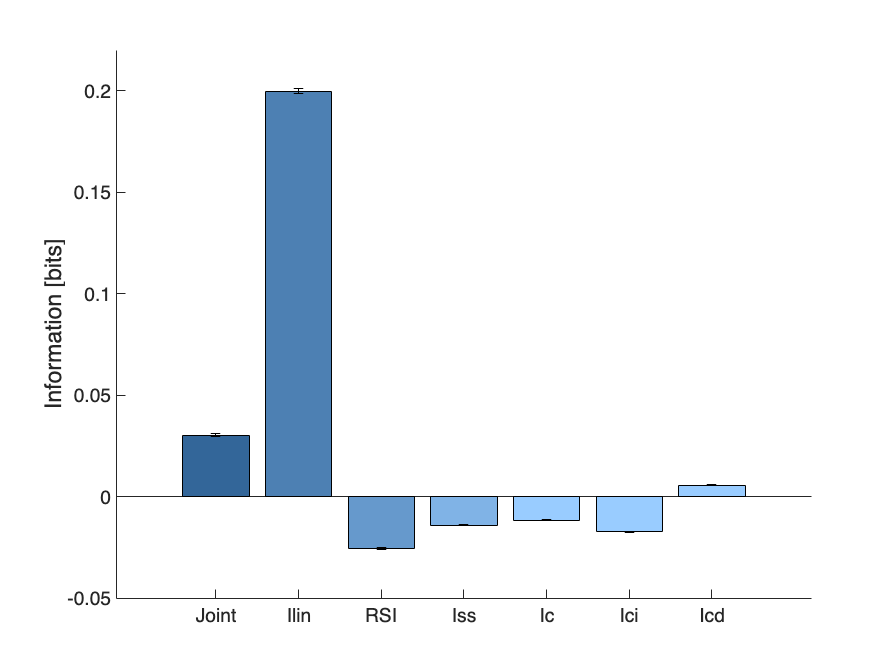


% Compute mean across repetitions
for bdwIdx = 1:numel(info_bdw_terms)
    bdwLab = info_bdw_terms{bdwIdx};
    eval([bdwLab '_all = reshape(MI_breakdown.(bdwLab), 1, []);']);
end


resAll = mean_SEM({Ilin_all, RSI_all, Iss_all, Ic_all, Ici_all, Icd_all}, {'MeanAll', 'SEMAll'});

[meanAll, errAll] = resAll{:};

[meanIlin, meanRSI, meanIss, meanIc, meanIci, meanIcd] = meanAll{:};
[errIlin, errRSI, errIss, errIc, errIci, errIcd]       = errAll{:};


% Plot 
colorInfoBreak = [0.2, 0.4, 0.6];
colorShift = [0.1, 0.1, 0.1]; 
figure;
hold on;

scIdx = 1;
fontsize = 12;

bar(scIdx, meanJoint, 'FaceColor', colorInfoBreak, 'DisplayName', 'Joint');
errorbar(scIdx, meanJoint, errJoint, 'k--');

scIdx = scIdx + 1;
bar(scIdx, meanIlin, 'FaceColor', colorInfoBreak + colorShift, 'DisplayName', 'Ilin');
errorbar(scIdx, meanIlin, errIlin, 'k--');

scIdx = scIdx + 1;
bar(scIdx, meanRSI, 'FaceColor', colorInfoBreak + 2*colorShift, 'DisplayName', 'Ilin');
errorbar(scIdx, meanRSI, errRSI, 'k--');

scIdx = scIdx + 1;
bar(scIdx, meanIss, 'FaceColor', colorInfoBreak + 3*colorShift, 'DisplayName', 'Iss');
errorbar(scIdx, meanIss, errIss, 'k--');

scIdx = scIdx + 1;
bar(scIdx, meanIc, 'FaceColor', colorInfoBreak + 4*colorShift, 'DisplayName', 'Ic');
errorbar(scIdx, meanIc, errIc, 'k--');

scIdx = scIdx + 1;
bar(scIdx, meanIci, 'FaceColor', colorInfoBreak + 4*colorShift, 'DisplayName', 'Ici');
errorbar(scIdx, meanIci, errIci, 'k--');

scIdx = scIdx + 1;
bar(scIdx, meanIcd, 'FaceColor', colorInfoBreak + 4*colorShift, 'DisplayName', 'Icd');
errorbar(scIdx, meanIcd, errIcd, 'k--');

ylabel('Information [bits]', 'FontSize', fontsize);
xticks(1:scIdx);
xticklabels({'Joint', 'Ilin','RSI','Iss', 'Ic', 'Ici', 'Icd'});

ylim([-0.05, 0.22]); 
set(gca, 'FontSize', fontsize);
hold off;

In this configuration, rendundancy is larger than synergy (because all neurons have the same trial-averaged response profiles to the stimuli) and correlations reduce information (because they are elongated along the axis separating the mean firing rates of individual neurons and thus increase the overlap between the stimulus-specific distributions of neural activity). Negative co-information arises because of larger redundancy (created by so called signal similarity expressing the similarity of tuning to stimuli of individual neurons) than synergy (created by the small but present stimulus-modulation of correlations). Information Breakdown analysis reveals that indeed information is more redundant because the signal-noise similarity (captured by I_sig-sim and I_cor-ind ) is larger than the small stimulus-dependent correlations.    

**Example 2: Information enhancing Correlations**

In this example, only correlations between activity of different neurons, but not the single-neuron activities, are stimulus-modulated and thus encode stimulus information. Therefore the correlations are information enhancing. 

nNeurons = 20; 
nPairs = nNeurons*(nNeurons-1)/2;
nTrials_per_stim = 200; 
nShuff = 2; 
tPoints = 500; 
bdw_bins = 5;% number of bins used to discretize spike counts for information breakdown calculations

nReps = 5;
info_bdw_terms = {'Joint','Ilin','RSI','Iss','Ic','Ici','Icd'};
for repIdx = 1:nReps
    disp(['Repetition number ', num2str(repIdx)])
    
    % Simulate Stimulus
    S = [1*ones(1,nTrials_per_stim),2*ones(1,nTrials_per_stim)];

    % Parameters
    lambda_1 = 1;
    lambda_2 = 2;
    lambda_noise_1 = 1;
    lambda_noise_2 = 0;

    % Simulate neural response
    R_1 = zeros(nNeurons,tPoints,nTrials_per_stim);
    R_2 = zeros(nNeurons,tPoints,nTrials_per_stim);
    for trialIdx = 1:nTrials_per_stim
        [spikes1_noise] = poisson_spike_gen(1:tPoints, lambda_noise_1/tPoints, 0);
        [spikes2_noise] = poisson_spike_gen(1:tPoints, lambda_noise_2/tPoints, 0);
        for cellIdx = 1:nNeurons
            [spikes1] = poisson_spike_gen(1:tPoints, lambda_1/tPoints, 0);
            [spikes2] = poisson_spike_gen(1:tPoints, lambda_2/tPoints, 0);
            R_1(cellIdx,:,trialIdx) = spikes1 + spikes1_noise;
            R_2(cellIdx,:,trialIdx) = spikes2 + spikes2_noise;
        end
    end
    R_1_count = squeeze(sum(R_1,2));
    R_2_count = squeeze(sum(R_2,2));
    R = [R_1_count,R_2_count];
    pairlist = nchoosek(1:nNeurons,2);
    MI_v = cell(length(pairlist), length(info_bdw_terms));
    parfor pairi = 1:length(pairlist) % remove par to make it not parallel
        cell1 = pairlist(pairi,1);
        cell2 = pairlist(pairi,2);
        resp1 = R(cell1,:);
        resp2 = R(cell2,:);
        resp1(resp1>bdw_bins -1) = bdw_bins -1;
        resp2(resp2>bdw_bins -1) = bdw_bins -1;
        jointResp = [resp1;resp2];
        MI_v(pairi, :) = MI({jointResp,S}, reqOutputs, MI_opts);
    end
    for bdwIdx = 1:numel(info_bdw_terms)
        bdwLab = info_bdw_terms{bdwIdx};
        for pairi = 1:length(pairlist)
            MI_breakdown.(bdwLab)(repIdx,pairi) = MI_v{pairi,bdwIdx};
        end
    end
end

Repetition number 1
Repetition number 2
Repetition number 3
Repetition number 4
Repetition number 5


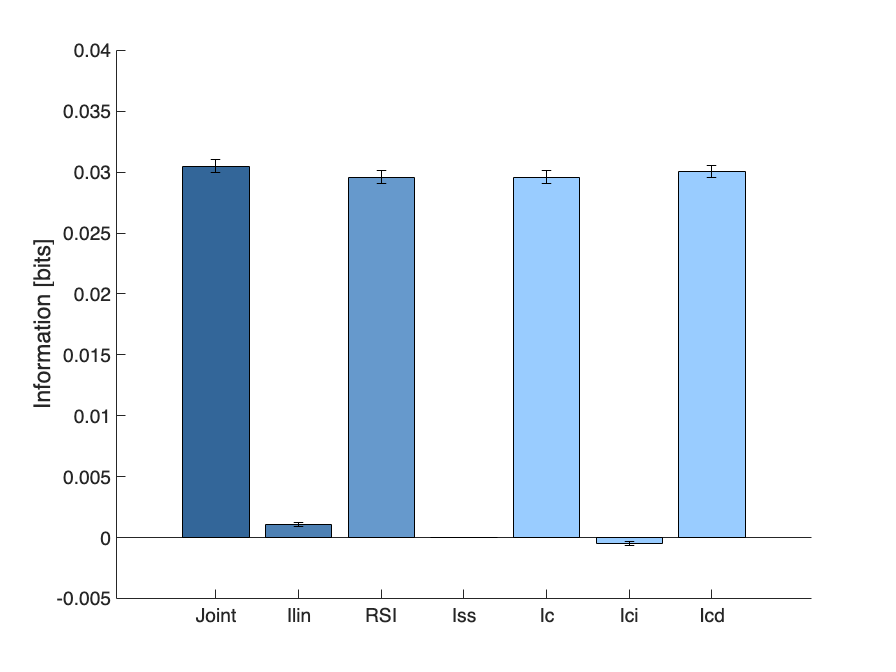


% Compute mean across repetitions
for bdwIdx = 1:numel(info_bdw_terms)
    bdwLab = info_bdw_terms{bdwIdx};
    eval([bdwLab '_all = reshape(MI_breakdown.(bdwLab), 1, []);']);
end

resAll = mean_SEM({Ilin_all, RSI_all, Iss_all, Ic_all, Ici_all, Icd_all}, {'MeanAll', 'SEMAll'});

[meanAll, errAll] = resAll{:};

[meanIlin, meanRSI, meanIss, meanIc, meanIci, meanIcd] = meanAll{:};
[errIlin, errRSI, errIss, errIc, errIci, errIcd]       = errAll{:};


% Plot 
colorInfoBreak = [0.2, 0.4, 0.6]; 
colorShift = [0.1, 0.1, 0.1]; 
figure;
hold on;

scIdx = 1;
fontsize = 12;

bar(scIdx, meanJoint, 'FaceColor', colorInfoBreak, 'DisplayName', 'Joint');
errorbar(scIdx, meanJoint, errJoint, 'k--');

scIdx = scIdx + 1;
bar(scIdx, meanIlin, 'FaceColor', colorInfoBreak + colorShift, 'DisplayName', 'Ilin');
errorbar(scIdx, meanIlin, errIlin, 'k--');

scIdx = scIdx + 1;
bar(scIdx, meanRSI, 'FaceColor', colorInfoBreak + 2*colorShift, 'DisplayName', 'Ilin');
errorbar(scIdx, meanRSI, errRSI, 'k--');

scIdx = scIdx + 1;
bar(scIdx, meanIss, 'FaceColor', colorInfoBreak + 3*colorShift, 'DisplayName', 'Iss');
errorbar(scIdx, meanIss, errIss, 'k--');

scIdx = scIdx + 1;
bar(scIdx, meanIc, 'FaceColor', colorInfoBreak + 4*colorShift, 'DisplayName', 'Ic');
errorbar(scIdx, meanIc, errIc, 'k--');

scIdx = scIdx + 1;
bar(scIdx, meanIci, 'FaceColor', colorInfoBreak + 4*colorShift, 'DisplayName', 'Ici');
errorbar(scIdx, meanIci, errIci, 'k--');

scIdx = scIdx + 1;
bar(scIdx, meanIcd, 'FaceColor', colorInfoBreak + 4*colorShift, 'DisplayName', 'Icd');
errorbar(scIdx, meanIcd, errIcd, 'k--');

ylabel('Information [bits]', 'FontSize', fontsize);
xticks(1:scIdx);
xticklabels({'Joint', 'Ilin','RSI','Iss', 'Ic', 'Ici', 'Icd'});

ylim([-0.005, 0.04]); 
set(gca, 'FontSize', fontsize);
hold off;

Positive co-information arises because of large synergy with negligible redundancy. The Information Breakdown reveals that all the synergistic information is due to stimulus-dependent correlations.